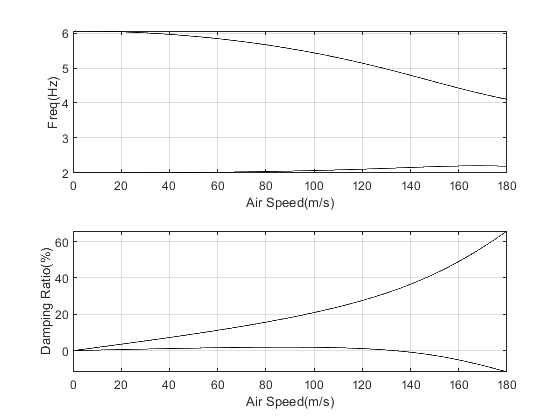

%Pgm_G1_Calcs
%Setsuptheaeroelasticmatricesforbinaryaeroelasticmodel, %performseigenvaluesolutionatdesiredspeedsanddeterminesthe frequencies
%anddampingratios
%plotsV_omegaandV_gtrends
%Initializevariables clear;clf
%Systemparameters	
s=7.5;	            %semispan
c=2.086;	                %chord
m=68.772;	                % mass/area of wing
flap_freq=2;	                    %flapping freq in Hz
theta_freq=6;	                    %pitch freq in Hz
xcm=0.4*c;	                %position of centre of mass from leading edge
xf=0.35*c;	                                        %position of flexural axis from leading edge
e=xf/c - 0.25;	                            %eccentricity between flexural axis and aerodynamic centre(1/4chord)
velstart=1;	                                        %lowest velocity
velend=180;	                        %maximum velocity
velinc=0.1;	                                %velocity increment
a=2*pi;	                                    %2D lift curve slope
rho=1.225;	                                    %air density
Mthetadot=-1.2;	                            %unsteady aero damping term
M=(m*c^2-2*m*c*xcm)/(2*xcm);	                        %leading edge mass term
damping_Y_N=1;	                                            % 1 if damping included and 0 if not included 

                                                            %structural proportional damping inclusion
                                                                     %C=alpha*M+beta*K

                                                                    %then two freqs and damps must be defined
if damping_Y_N==1                                                                %set damping to zero for no structural damping
    z1=0.0;	                                                                %critical damping at firstfrequency
    z2=0.0;	                                            %critical damping at second frequency 
    w1=2*2*pi;	                                                                        %firstfrequency 
    w2=14*2*pi;	                                                                        %secondfrequency
    alpha=2*w1*w2*(-z2*w1+z1*w2)/(w1*w1*w2*w2); 
    beta=2*(z2*w2-z1*w1)/(w2*w2-w1*w1);
end
                                                                %Set up system matrices %Inertiamatrix 
a11=(m*s^3*c)/3+M*s^3/3;                                            %Ikappa
a22=m*s*(c^3/3-c*c*xf+xf*xf*c)+M*(xf^2*s);                              %Itheta 
a12=m*s*s/2*(c*c/2-c*xf)-M*xf*s^2/2;                                    %Ikappatheta 
a21=a12;
A=[a11,a12;a21,a22];
                                                                    %Structuralstiffnessmatrix 
k1=(flap_freq*pi*2)^2*a11;                                         %kkappa   heavestiffness 
k2=(theta_freq*pi*2)^2*a22;                                 %  ktheta pitch stiffness
E=[k1 0;0 k2];

icount=0; 
for V=velstart:velinc:velend                                            %loop for different velocities 
    icount=icount+1;
    if damping_Y_N==0	                                        %damping matrices
        C=[0,0;0,0];	                                            % if   damping  not  included 
    else	                                            %    if   damping    included
        C=rho*V*[c*s^3*a/6,0;-c^2*s^2*e*a/4,-c^3*s*Mthetadot/8]+ alpha*A+beta*E;
    end
                                                                                    %  Aero and structural damping end
    K=(rho*V^2*[0,c*s^2*a/4;0,-c^2*s*e*a/2])+[k1,0;0,k2];                               % aero/structuralstiffness
    Mat=[[0,0;0,0],eye(2);-A\K,-A\C];	                                                %setup 1st order eigenvalue solution matrix
	lambda=eig(Mat);
                                                 %Naturalfrequenciesanddampingratios 
    for jj=1:4 
        im(jj) = imag(lambda(jj)); re(jj) = real(lambda(jj));
        freq(jj,icount) = sqrt(re(jj)^2+im(jj)^2); 
        damp(jj,icount) =-100*re(jj)/freq(jj,icount);
        freq(jj,icount) = freq(jj,icount)/(2*pi);
    end
    Vel(icount)=V; 
end
                                                        %Plotfrequenciesanddampingsvsspeedfigure(1) 
subplot(2,1,1);plot(Vel,freq,'k');vaxis=axis; 
xlim=([0 vaxis(2)]); xlabel('Air Speed(m/s)'); ylabel('Freq(Hz)');grid

subplot(2,1,2); plot(Vel,damp,'k')
xlim=([0 vaxis(2)]); axis([xlim ylim]);
xlabel('Air Speed(m/s)'); ylabel('Damping Ratio(%)'); grid